clc; clear all; close all;

#### Generating Random Data to Transmit

% Creating X_k - Randomly choose between 1 and -1
size_training_data = 64*16;
size_X = 64*84; %Size of data - 100 sets of 64 bits
range = [-1 1]; %List of wanted values
a = randi(2,size_X,1); %Randomly select index
b = randi(2,size_training_data,1); 

Create Data and Training Data

X_k = transpose(range(a)); %Creates array with range(a) values
X_train = transpose(range(b)); %Training Data
message = [X_train ; X_k];

#### IDFT - Takes inverse discrete fourier tranform of data

x_m = ifft(message); %Turns data points into impulses

#### Adding cyclic prefix

n_data = size_X/64 + size_training_data/64; % Calculates amount of sets of d-bit data chunks from original data
tx_data = [];

%Index 1st cyclic prefix - Done to ensure methodology works
cycPrefix = x_m(49: 64);                  % Determines index of first cyclic prefix - 16 bits
tx_data(1:16) = cycPrefix;                % Initializes array that will hold data w/ prefix
tx_data(17:80) = x_m(1: 64);             % Loads first set of data  -  64 bits

%Index the Remaining Data
for R = 2:1:n_data  % Adds cyclic prefixes
    cycPrefix = x_m(64*(R-1)+ 48+1: 64*(R));
    tx_data(1 + 80*(R-1): 16*R + 64*(R-1)) = cycPrefix;
    Post_chunk =  x_m(64*(R-1)+1: 64*(R));
    tx_data(1 + 16*R + 64*(R-1) : 16*R + 64*R) = Post_chunk;
end
tx_data = transpose(tx_data)

tx_data =    0.0041 + 0.0086i
  -0.0039 + 0.0004i
   0.0038 + 0.0140i
  -0.0026 - 0.0065i
  -0.0007 + 0.0025i
   0.0019 + 0.0050i
  -0.0066 - 0.0018i
   0.0185 - 0.0037i
   0.0039 + 0.0224i
   0.0201 + 0.0183i


#### Transmitting Data through nonflat channel function

Transmitting Training Data

% Transmit data through nonflat channel function
rx_data = nonflat_channel((tx_data));

Compensating for time delay

shift1_train = 9

Impulse_signal =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


impulseresponse =    0.0001 - 0.0003i
  -0.0013 - 0.0004i
   0.0003 - 0.0013i
  -0.0005 - 0.0003i
  -0.0003 - 0.0000i
   0.0010 + 0.0001i
   0.0003 + 0.0001i
  -0.0007 + 0.0001i
   0.0001 - 0.0002i
   0.0007 - 0.0012i


impulseresponse =   -0.1907 + 0.0003i
   0.9312 - 0.0003i
   0.2828 + 0.0000i
  -0.1988 + 0.0001i
   0.1621 + 0.0007i
  -0.1022 - 0.0014i
   0.0542 - 0.0004i
  -0.0271 - 0.0009i
   0.0083 + 0.0003i
  -0.0001 - 0.0001i


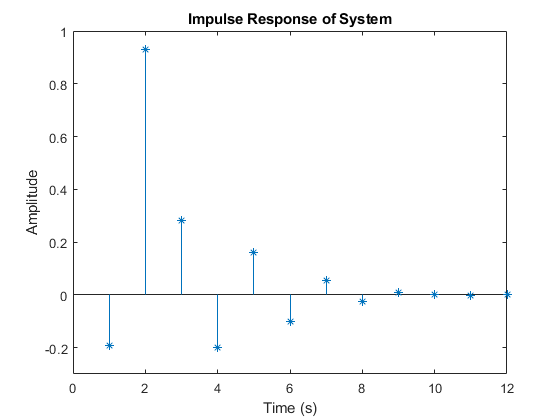

rx_conv =    0.0001 + 0.0004i
  -0.0013 - 0.0034i
   0.0044 + 0.0071i
  -0.0019 + 0.0002i
   0.0002 + 0.0098i
   0.0028 + 0.0048i
  -0.0061 - 0.0096i
   0.0056 + 0.0108i
  -0.0108 + 0.0004i
   0.0087 - 0.0129i


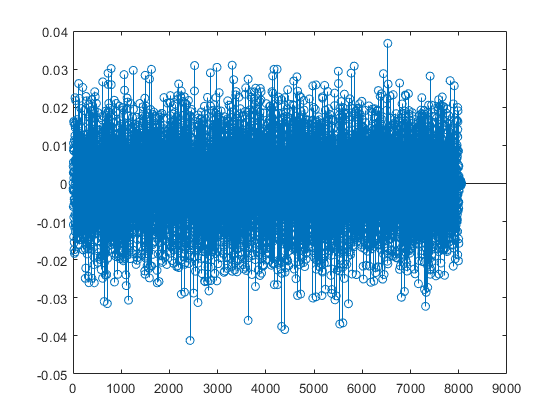

% Determine Lag in Data
[y1x1,lag1] = xcorr(rx_data,tx_data); 

[~, Index] = max(abs(y1x1));
shift1_train = lag1(Index)
%Comes out to be 9

%Cut Data from Lag
rx_data = rx_data(shift1_train:end);

Estimate Channel

#### Retrieving 6400 data bits from received signal

Move received time signal to the frequency domain using FFT

%% FFT - Fast Fourier Transform of Received Data
Y_k = fft(rx_conv);

Normalize Y_k

Norm_Y_k =(real(Y_k)./abs(real(Y_k)));

Cut Data

Index_data = length(Norm_Y_k) - length(message);
Retrieved_data = transpose((Norm_Y_k(Index_data + 1:end)));

Plot Y_k

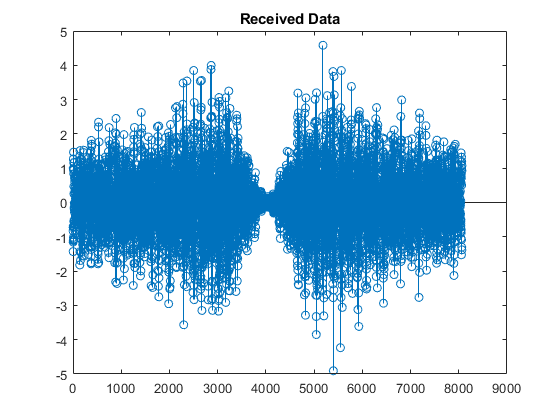

figure;
stem(real(Y_k));
hold on

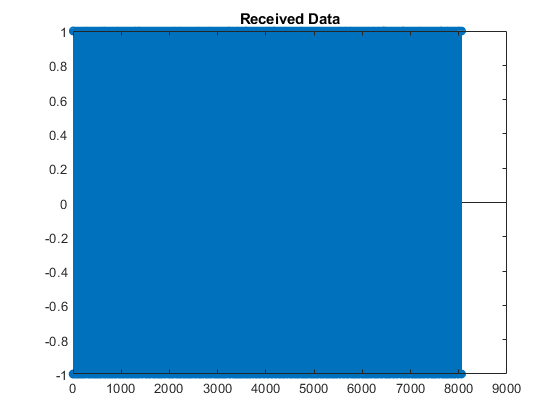

title('Received Data')
hold off

figure;
stem(real(Norm_Y_k));
hold on

title('Received Data')
hold off

#### Transmitted Vs Received Data

% Calculating Error
diff = (message - Retrieved_data)./(2*message);
Error = abs(mean(diff)) *100

Error =    50.5938   50.5938   49.4063   49.4063   50.5938   50.5938   49.4063   49.4063   49.4063   50.5938   49.4063   50.5938   49.4063   49.4063   50.5938   49.4063   49.4063   50.5938   49.4063   49.4063   50.5938   50.5938   49.4063   50.5938   49.4063   50.5938   49.4063   49.4063   49.4063   50.5938   49.4063   49.4063   50.5938   50.5938   50.5938   50.5938   49.4063   49.4063   50.5938   49.4063   49.4063   49.4063   50.5938   50.5938   49.4063   50.5938   50.5938   50.5938   49.4063   50.5938


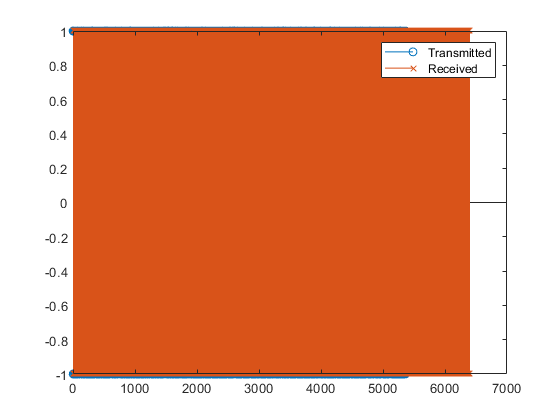


%Plotting Data
stem(real(X_k),'o') % Plotting Transmitted Data
hold on
stem(real(Retrieved_data),'x')% Plotting Received Data
legend('Transmitted','Received')
hold off

Channel Estimation 

With OFDM, we are assuming flat fading model for every 64 bits of data, giving us 100 different transfer functions

% H_k = zeros(100,1); %Empty vector to put transfer function values
% 
% for H = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     ChannelEst_n = mean(Y_k(1 + 64*(H-1): 64*(H))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     H_k(H) = ChannelEst_n; %Place data into Transfer function matrix
% end
% figure;
% stem(real(H_k));
% hold on
% title('Transfer Functions of Data');
% hold off
% 

Estimation of Noise

% est_noise = var(noise_thru_channel)
% 
% for Z = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     w = ((conj(H_k(Z))));
%     Y_ret = (conj(w)).*(Y_k(1 + 64*(Z-1): 64*(Z))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     Retrieved_data(1 + 64*(Z-1): 64*(Z)) = Y_ret; %Place data into Transfer function matrix
% end
Retrieved_data = transpose(Retrieved_data)

Retrieved_data =     -1
    -1
     1
     1
    -1
    -1
     1
     1
     1
    -1


Estimate Channel Impulse Response

% Alpha_z = zeros(640,1);
% Impulse = ones(1,1);
% Beta_z = zeros(640,1);
% 
% Impulse_signal = [Alpha_z ; Impulse ; Beta_z]
% impulseresponse = nonflat_channel(Impulse_signal)
% impulseresponse = impulseresponse(649:660)
% figure;
% stem(impulseresponse,'*')
% hold on
% title('Impulse Response of System')
% xlabel('Time (s)');
% ylabel('Amplitude');
% ylim([-.3,1]);
% hold off

Circular Convolution

% rx_conv = conv(impulseresponse, rx_data)
% stem(rx_conv)

Realign

% % Determine Lag in Data
% [y1x1,lag1] = xcorr(rx_conv, rx_data); 
% [~, Index] = max(abs(y1x1));
% shift2 = lag1(Index)
% %Comes out to be 9
% 
% %Cut Data from Lag
% rx_data = rx_data(shift2:end);